This package is designed for presenting the Fourier transformation of the Gaussian package, in the light of the section 3.1-3.3 in Zinn-Justin's book.

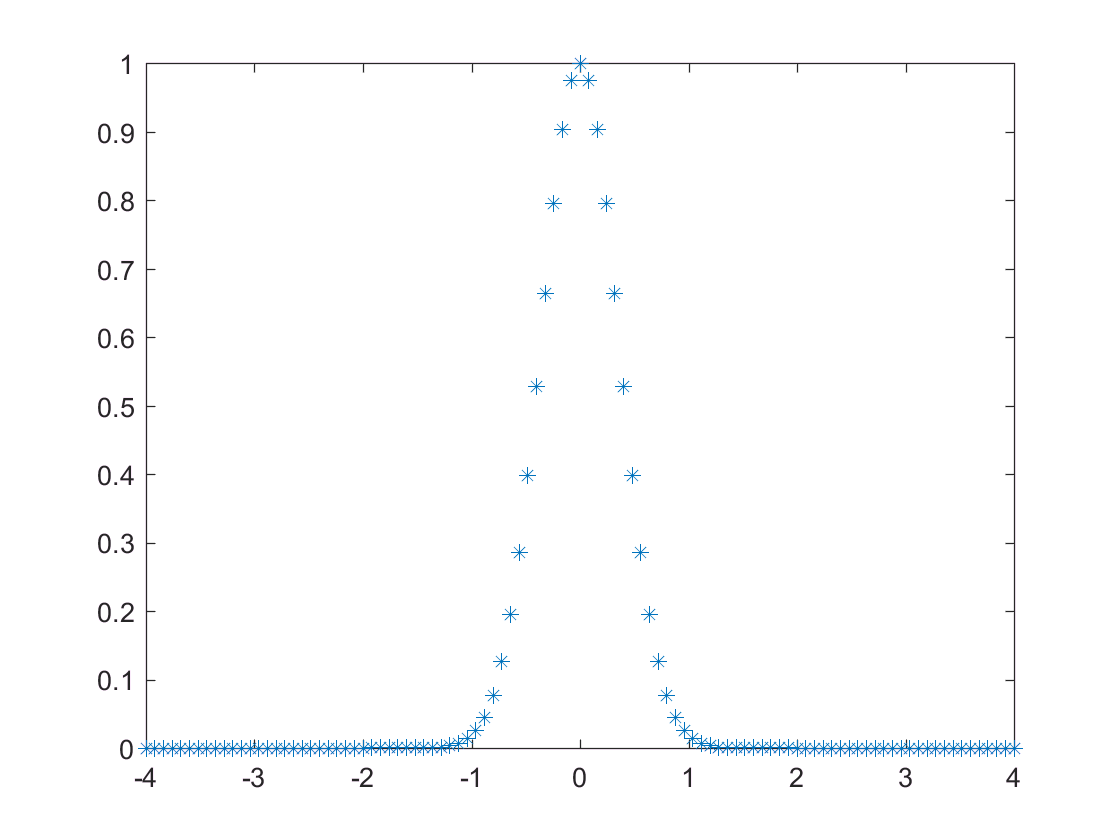

clear;
Num=101;
xcut=4;
delta=2*xcut/(Num-1);
period=2*xcut+2*xcut/(Num-1);
v_base=linspace(-xcut,xcut,Num);
v_y=exp(-4*v_base.^2);
figure(2);
plot(v_base,v_y,'*');

v_nt=zeros(1,Num);
v_length=v_base(2:Num)-v_base(1:Num-1);
v_x_nt=zeros(1,Num);
v_x_nt(1:Num-1)=1/2*v_length;
v_x_nt(2:Num)=v_x_nt(2:Num)+1/2*v_length;
int_package=sum(v_x_nt.*v_y);
disp(['int gauss=',num2str(int_package)]);

int gauss=0.88623


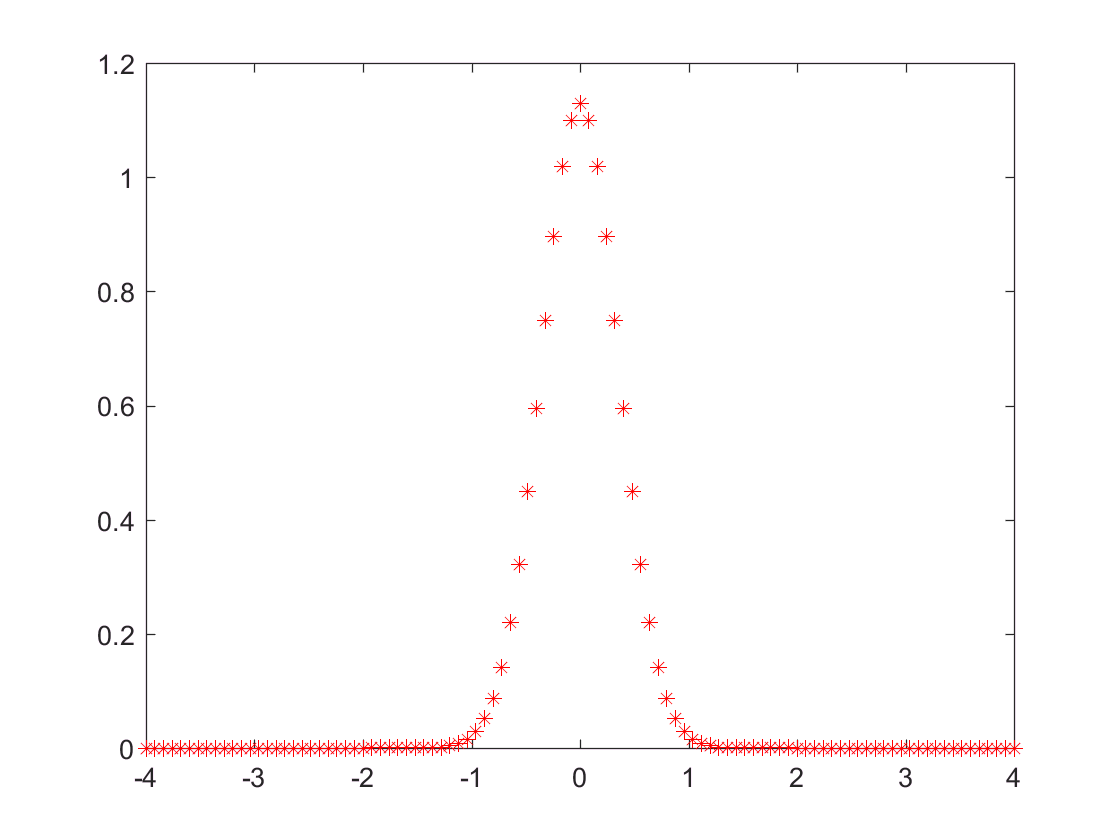

v_y=v_y/int_package;
plot(v_base,v_y,'r*');

next we use the function fft to do the Fourier transformation. We must prepare our v_base and v_y in the manner of the positive defiend x-region. 

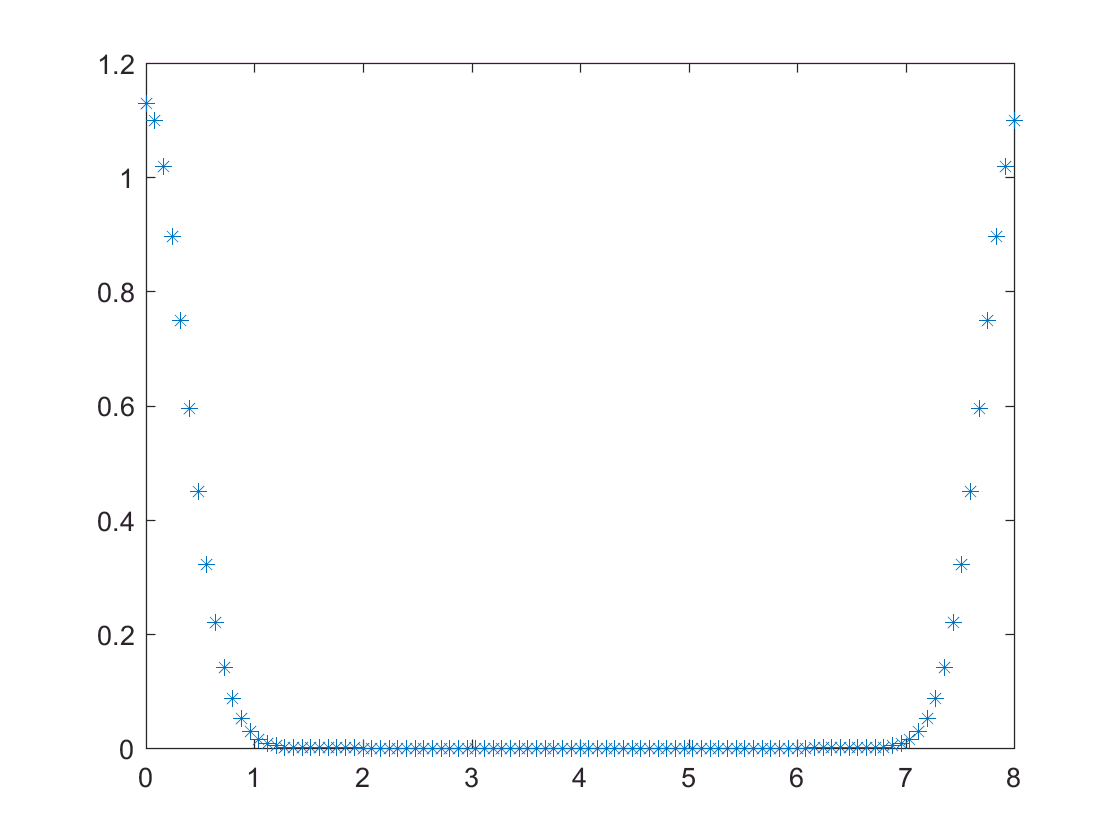

v_base=[v_base((Num+1)/2:Num),v_base(1:(Num-1)/2)+period];
v_y=[v_y((Num+1)/2:Num),v_y(1:(Num-1)/2)];
plot(v_base,v_y,'*');

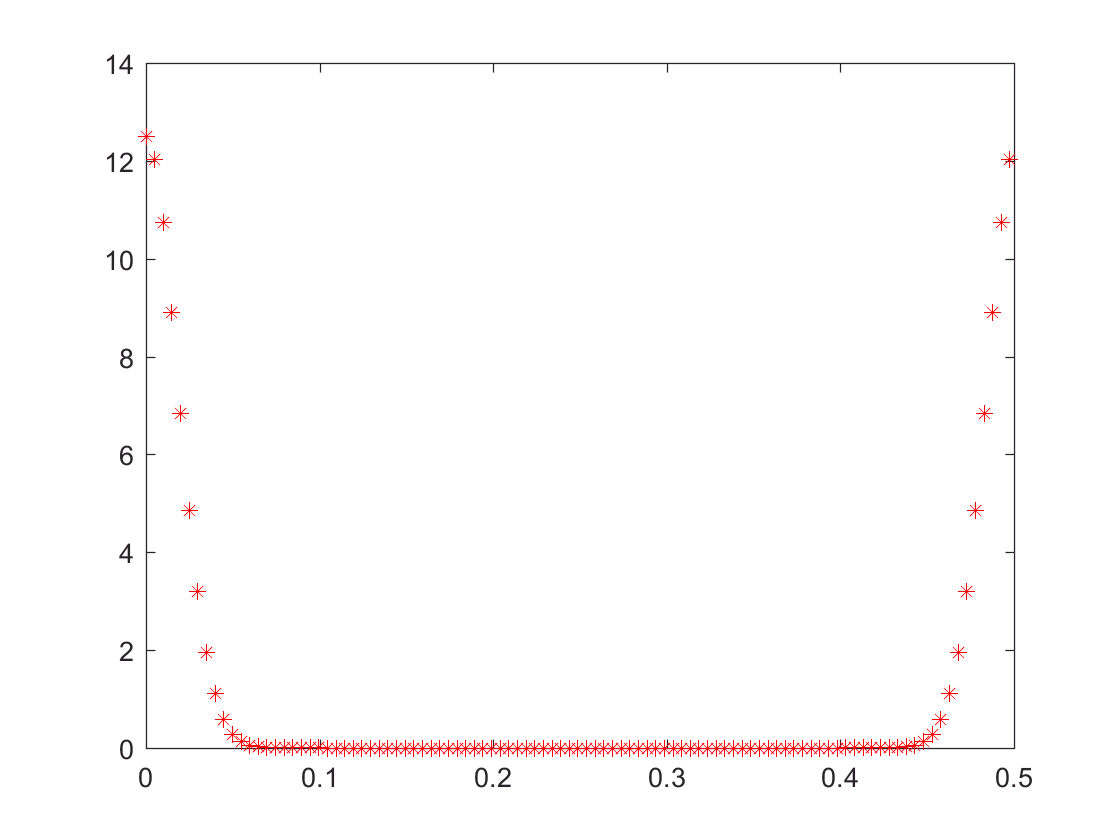


v_k=fft(v_y);
v_k_base=(0:1:(Num-1))*2*pi/Num*delta;
plot(v_k_base,abs(v_k),'r*');